# 1D Heat Transfer

Algorithm 1D heat transfer can be describe by the following PDE equation.


$$\rho c\frac{\partial T}{\partial t}=\frac{\partial}{\partial x}(\lambda\frac{\partial 
T}{\partial x})+Q$$


With a simple boundary condition:


$$\begin{cases}T(x,0)=0\\Q(x=x_{max})=1\end{cases}$$


And to further simplify the problem, we assume that


$$\rho=c=\lambda=1$$


Therefore, we want to slove:

                                                        
$$$\frac{\partial T}{\partial t}=\frac{\partial^2 T}{\partial x^2}+Q$$


### Forward Eular time-marching

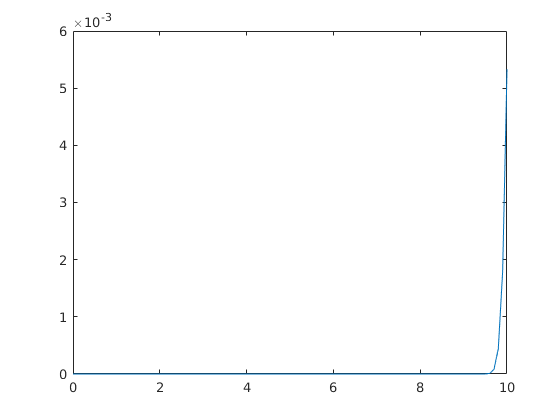

h = 0.1;
Q = 1;
x = 0:h:10;
T = zeros(1,length(x));
dt = 0.001;
iter = 10;
for i = 1:iter
    T = explicit_time_marching(T, Q, h, dt);
end
plot(x,T)

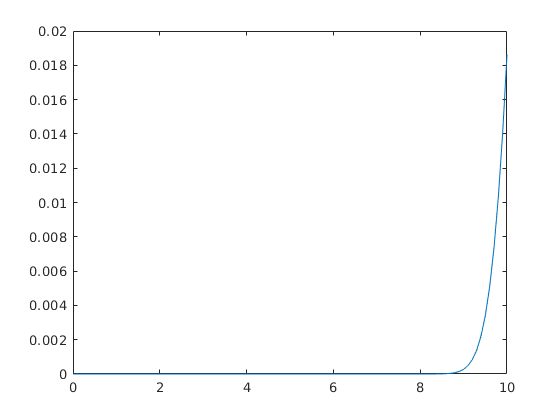

iter = 100;
for i = 1:iter
    T = explicit_time_marching(T, Q, h, dt);
end
plot(x,T)

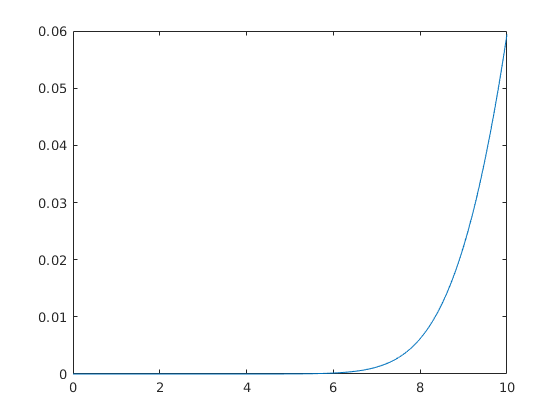

iter = 1000;
for i = 1:iter
    T = explicit_time_marching(T, Q, h, dt);
end
plot(x,T)

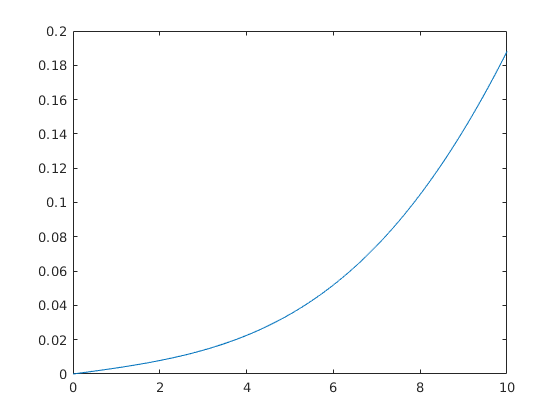

iter = 10000;
for i = 1:iter
    T = explicit_time_marching(T, Q, h, dt);
end
plot(x,T)

### Backward Euler time-marching

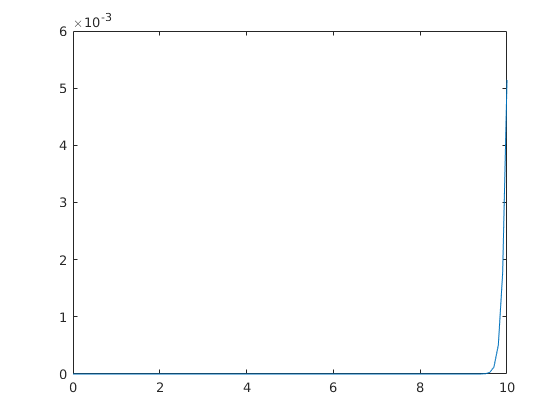

h = 0.1;
Q = 1;
x = 0:h:10;
T = zeros(1,length(x));
dt = 0.001;
iter = 10;
for i = 1:iter
    T = implicit_time_marching(T, Q, h, dt);
end
plot(x,T)

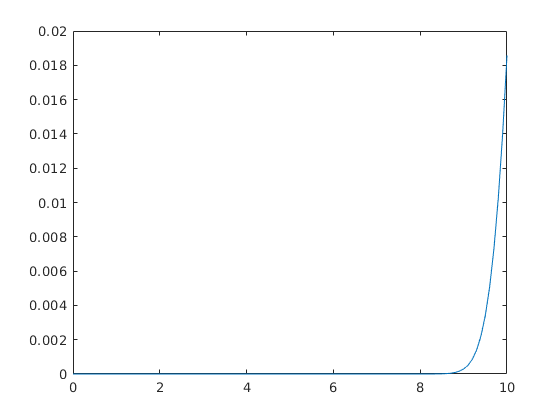

iter = 100;
for i = 1:iter
    T = implicit_time_marching(T, Q, h, dt);
end
plot(x,T)

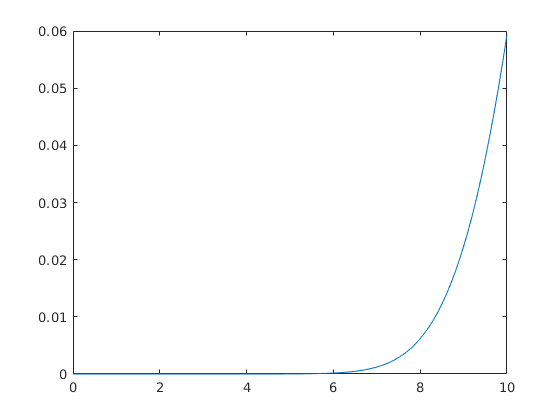

iter = 1000;
for i = 1:iter
    T = implicit_time_marching(T, Q, h, dt);
end
plot(x,T)

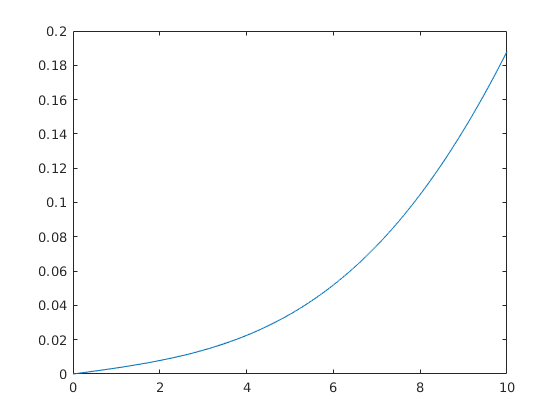

iter = 10000;
for i = 1:iter
    T = implicit_time_marching(T, Q, h, dt);
end
plot(x,T)

### MGRIT method

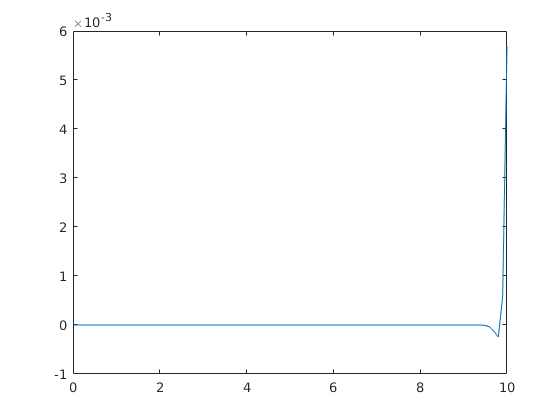

h = 0.1;
Q = 1;
x = 0:h:10;
l = length(x);
T = zeros(1,l);
dt = 0.001;
iter = 2;
time = 5;
T = MGRIT_PinST(T, Q, h, dt, time, iter);
plot(x,T((time-1)*l+1:time*l))


% time = 20;
% T = MGRIT_PinST(T, Q, h, dt, time, iter);
% plot(x,T((time-1)*l+1:time*l))